# **Trabalho 1 de AM2 - Interface Live Script**


addpath './Métodos'
clear;
cla;
clc;

%  ______   _   _   _____ 
%  | ___ \ | | | | |_   _|
%  | |_/ / | | | |   | |  
%  |  __/  | | | |   | |  
%  | |     \ \_/ /  _| |_ 
%  \_|      \___/  |_____| 

% Resolução de Problemas de Valor Inicial
% com recurso a Métodos Numéricos

escolha = "ODE45";

syms y(t);

s  =  "y*t^2+y";
a  =  1;
b  =  1.5;
n  =  20;
y0 =  2;
f = @(t,y) eval(vectorize(s));


try
    f(t,y);
catch
    errordlg("Introduza uma função em t e y","Erro");
    return
end

$$ans(t) = y\left(t\right)+t^{2}\,y\left(t\right)$$

if (not(isscalar(a) && isreal(a)))
    errordlg("O número introduzido para a é inválido","Erro");
    return
end

if (not(isscalar(b) && isreal(b) && b>a))
    errordlg("O número introduzido para b é inválido","Erro");
    return
end

if (not(isscalar(n) && isreal(n)))
    errordlg("O número introduzido para n é inválido","Erro");
    return
end

if (not(isscalar(y0) && isreal(y0))) 
    errordlg("O número introduzido para y0 é inválido","Erro");
    return
end


xExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);
g = @(t) eval(vectorize(char(xExata)));
h = (b-a)/n;
t = a:h:b;
yExata = g(t);
plot(yExata,'-r');
hold("on");


switch escolha
    case "Euler"
        sol = MEuler(f,a,b,n,y0);
        plot(sol,'-b');
        legend('Exata','Euler');
        hold("on");
    case "Euler+"
        sol = MEulerMelhorado(f,a,b,n,y0);
        plot(sol,'-b');
        legend('Exata','Euler+');
        hold("on");
    case "RK2"
        sol = NRK2(f,a,b,n,y0);
        plot(sol,'-b');
        legend('Exata','RK2');
        hold("on");
    case "RK4"
        sol = NRK4(f,a,b,n,y0);
        plot(sol,'-b');
        legend('Exata','RK4');
        hold("on");
    case "ODE45"
        sol = ode45(f,[a b],y0);
        plot(sol.y,'-b');
        legend('Exata','ODE45');
        hold("on");
    case "PSM"
        %%%%%%%
    case "Todos"
        Euler = MEuler(f,a,b,n,y0);
        EulerM = MEulerMelhorado(f,a,b,n,y0);
        RK2 = NRK2(f,a,b,n,y0);
        RK4 = NRK4(f,a,b,n,y0);
        ODE45 = ode45(f,[a b],y0).y;
end

title('Gráfico das soluções da PVI');

switch escolha
    case "Euler"
        tabela = [t.',yExata.',sol.'];
        array2table(tabela,"VariableNames",{'t','Exata','Euler'})
    case "Euler+"
        tabela = [t.',yExata.',sol.'];
        array2table(tabela,"VariableNames",{'t','Exata','Euler+'})
    case "RK2"
        tabela = [t.',yExata.',sol.'];
        array2table(tabela,"VariableNames",{'t','Exata','RK2'})
    case "RK4"
        tabela = [t.',yExata.',sol.'];
        array2table(tabela,"VariableNames",{'t','Exata','RK4'})
    case "ODE45"
        array2table(sol.',"VariableNames",{'ODE45'})
    case "PSM"
        %%%
    case "Todos"
        tabela = [t.',yExata.',Euler.',EulerM.',RK2.',RK4.'];
        array2table(tabela,"VariableNames",{'t','Exata','Euler','Euler+','RK2','RK4'})
        array2table(ODE45.',"VariableNames",{'ODE45'})
end

ans = table
       ODE45    
    ____________

    [1×1 struct]


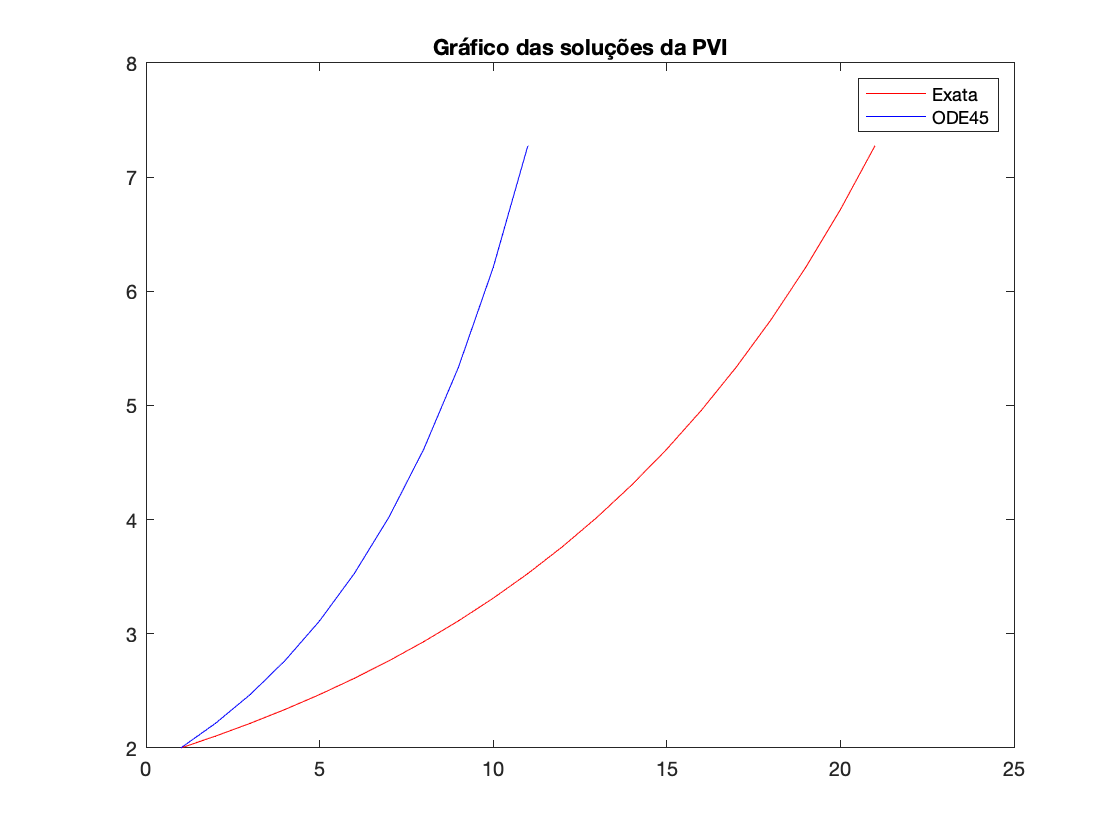


%%% Fazer um switch case para o plot


plot(Euler);

Unrecognized function or variable 'Euler'.

plot(EulerM);
plot(RK2);
plot(RK4);
plot(ODE45);
legend('Exata','Euler','Euler+','RK2','RK4','ODE45');
hold("on");
        
        
disp("SOLUÇÃO EXATA:    " + yExata(end));
disp("Solução Euler:    " + Euler(end));
disp("Solução Euler+:   " + EulerM(end));
disp("Solução RK2:      " + RK2(end));
disp("Solução RK4:      " + RK4(end));
disp("Solução ODE45:    " + ODE45(end));
        

fprintf('\n ')
disp("Iterações Euler:    " + length(Euler));
disp("Iterações Euler+:   " + length(EulerM));
disp("Iterações RK2:      " + length(RK2));
disp("Iterações RK4:      " + length(RK4));
disp("Iterações ODE45:    " + length(ODE45));


 